## This is all about symbolic variables

syms x;
y = x ^ 2;
y

$$y = x^{2}$$

solve(y - 1 == 0)

$$ans = \left(\begin{array}{c} -1\\ 1 \end{array}\right)$$

solve(x^2 - 2*x + 1)

$$ans = \left(\begin{array}{c} 1\\ 1 \end{array}\right)$$

solve(x^2 - 2*x - 5)

$$ans = \left(\begin{array}{c} 1-\sqrt{6}\\ \sqrt{6}+1 \end{array}\right)$$

solve(x^2 - 4*x + 4)

$$ans = \left(\begin{array}{c} 2\\ 2 \end{array}\right)$$

% we can also use 'single quotes'
solve(x^2-2*x+1==0)

$$ans = \left(\begin{array}{c} 1\\ 1 \end{array}\right)$$

syms x y;
z = (x + y) * (x - y);
z

$$z = \left(x+y\right)\,\left(x-y\right)$$


solve(z == 10)

$$ans = \left(\begin{array}{c} \sqrt{y^{2}+10}\\ -\sqrt{y^{2}+10} \end{array}\right)$$

expand(z)

$$ans = x^{2}-y^{2}$$

factor(ans)

$$ans = \left(\begin{array}{cc} x-y & x+y \end{array}\right)$$

z = (x^3-y^3)/(x-y);
simplify(z)

$$ans = x^{2}+x\,y+y^{2}$$

z = (x^3-y^3)/(x-y)

$$z = \frac{x^{3}-y^{3}}{x-y}$$

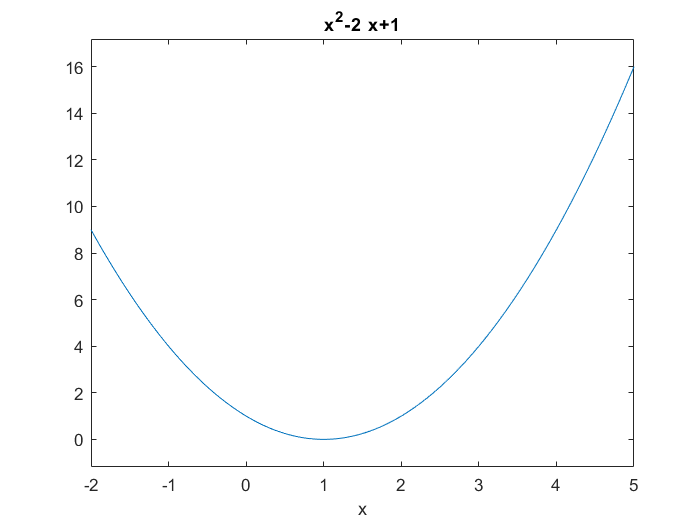

% plotting the graph of f(x) using ezplot(f(x), [lower higher])
ezplot('x^2-2*x+1', [-2 5]);

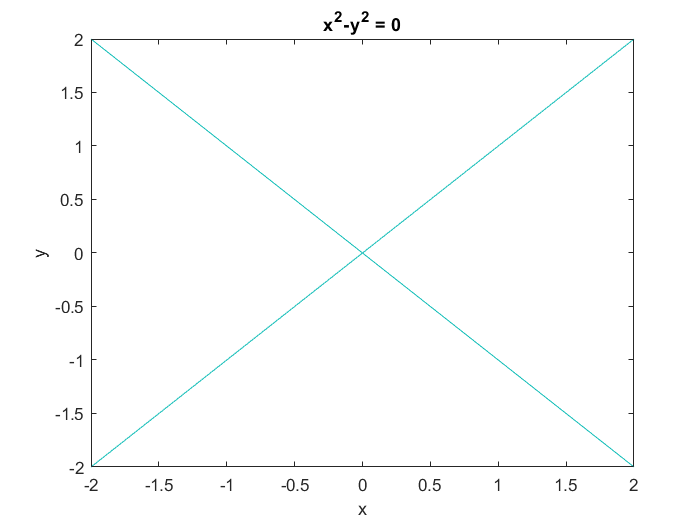

ezplot('x^2-y^2', [-2 2])

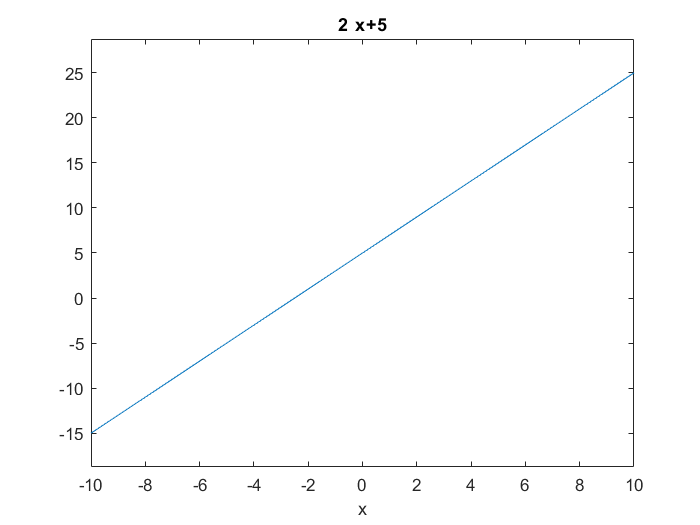

ezplot('2*x+5', [-10 10])

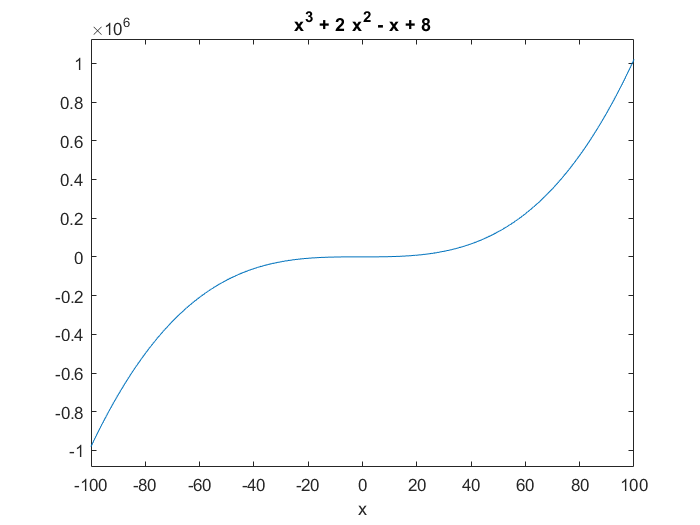

ezplot('x^3 + 2*x^2 - x + 8', [-100 100])

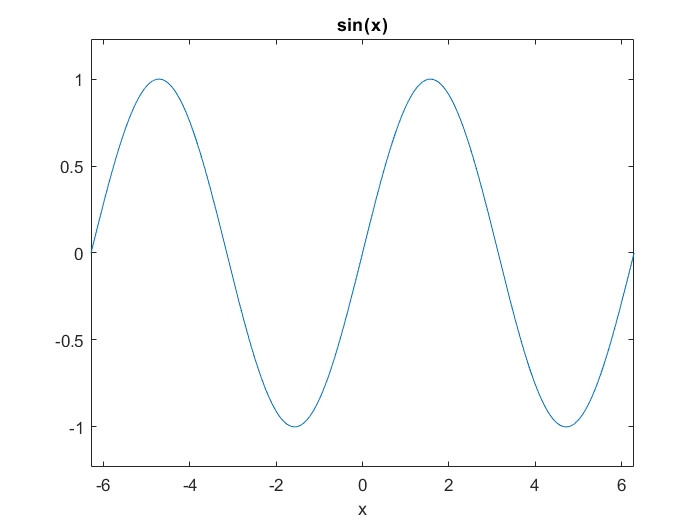

ezplot(sin(x))

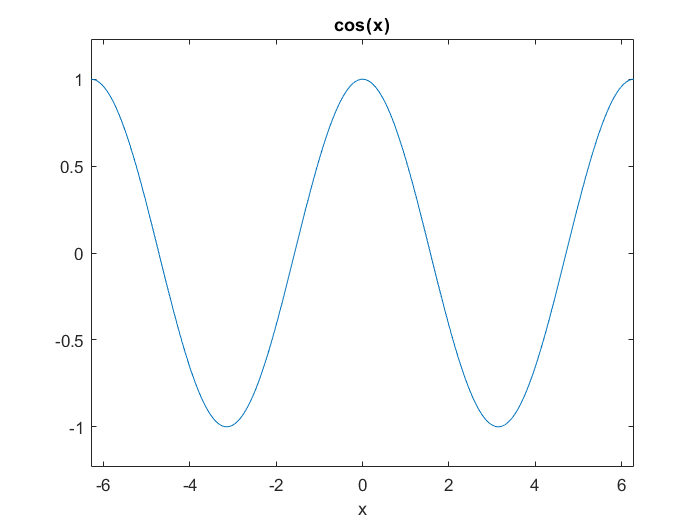

ezplot(cos(x))

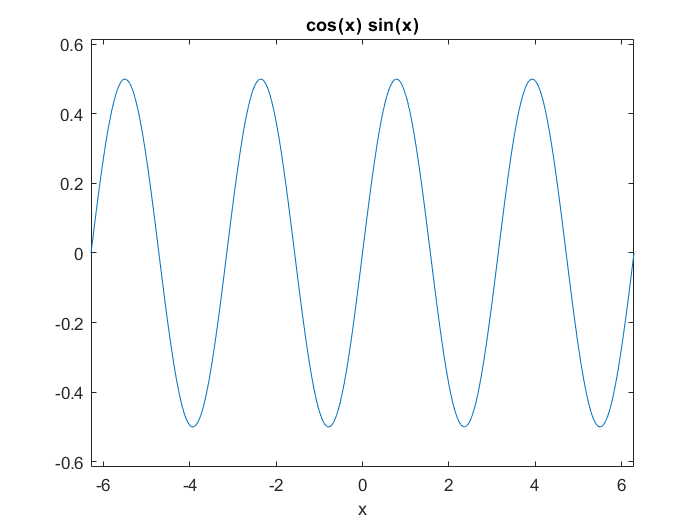

z = sin(x) * cos(x);
lower = -2*pi;
higher = 2*pi;
ezplot(z, [lower higher]);

% we can compose functions
z = sin(x) * cos(x);
lower = -2*pi;
higher = 2*pi;
ezplot(z, [lower higher]);

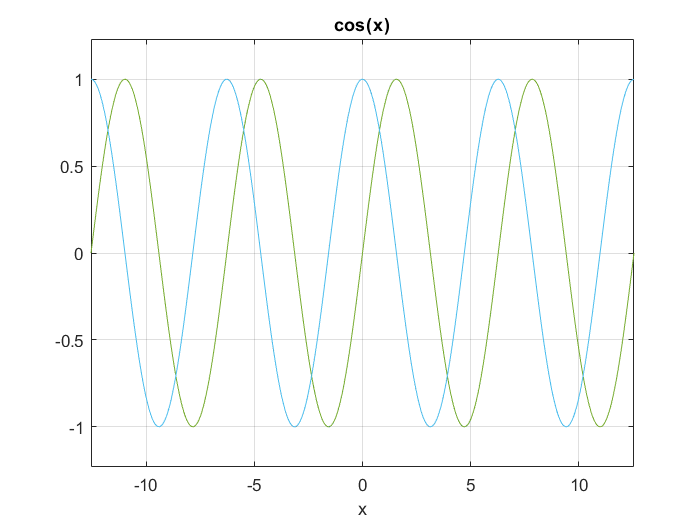

% plotting one over another
f1 = sin(x);
f2 = cos(x);
lower = -4*pi;
higher = 4*pi;
ezplot(f1, [lower, higher]);
hold on;
grid on;
ezplot(f2, [lower higher]);

% use of substitute
z = sin(x);
subs(z, x, 2);
ans

$$ans = \sin\left(2\right)$$

subs(sin(x), x, 2*pi)

$$ans = 0$$

subs(x^2, x, 8)

$$ans = 64$$

subs(x^3-y^3, x, 2)

$$ans = 8-y^{3}$$

subs(ans, y, 4)

$$ans = -56$$

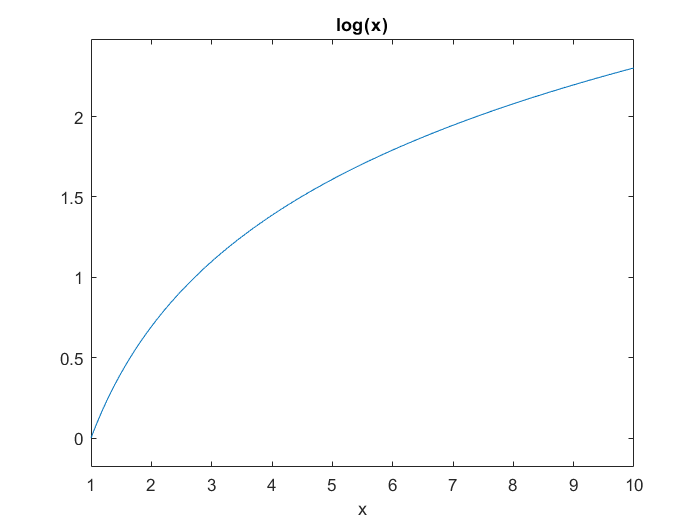

% plot the graph of log(x) using ezplot()
close all;
ezplot('log(x)', [1, 10])

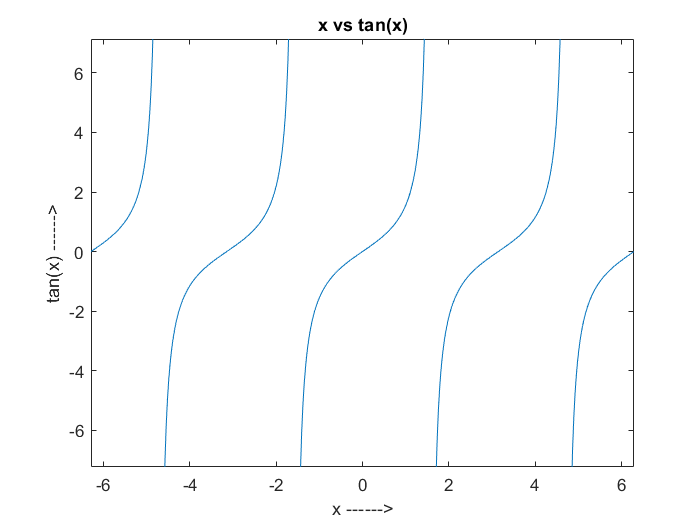


% plot tan(x) using ezplot()
ezplot(tan(x), [-2*pi 2*pi]);
xlabel("x ------>");
ylabel("tan(x) ------>");
title("x vs tan(x)");

% what is the value of cos(x) at x = pi/2
f = cos(x);
v = subs(f, x, pi/2)

$$v = 0$$